Problem 1 Plots

clear;
[y, n] = unit_impulse(0, -10, 10)

y =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0


n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


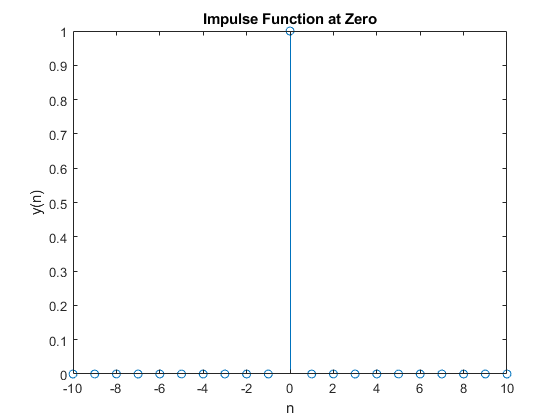

stem(n,y)
title('Impulse Function at Zero');
xlabel('n');
ylabel('y(n)');

[y, n] = unit_step(0, -10, 10)

y =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1


n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


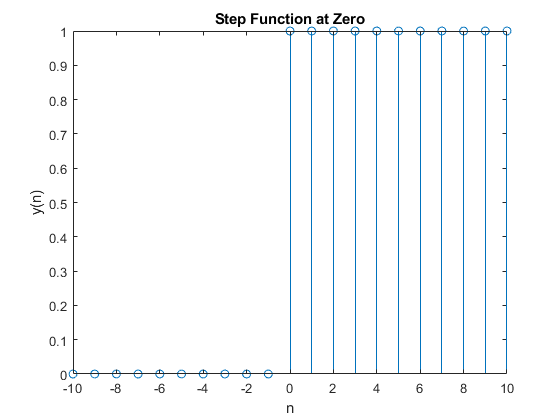

stem(n, y)
title('Step Function at Zero');
xlabel('n');
ylabel('y(n)');

Problem 2 Time Shift Plot

[y, n] = time_shift(y, n, 3)

y =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1


n =     -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13


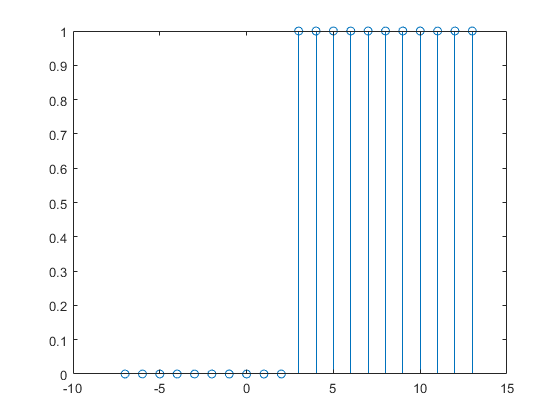

stem(n, y)

Problem 2.2 Plots

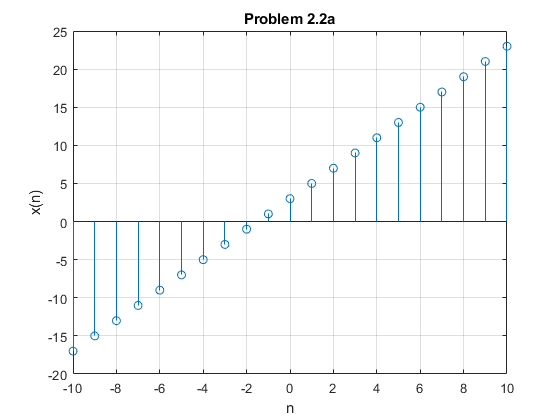

clear;
n = -10:10;
x = (2*n)+3;
stem(n, x)
grid on;
title('Problem 2.2a');
xlabel('n');
ylabel('x(n)');


[x_delay, n] = time_shift(x, n, 3)

x_delay =    -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23


n =     -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13


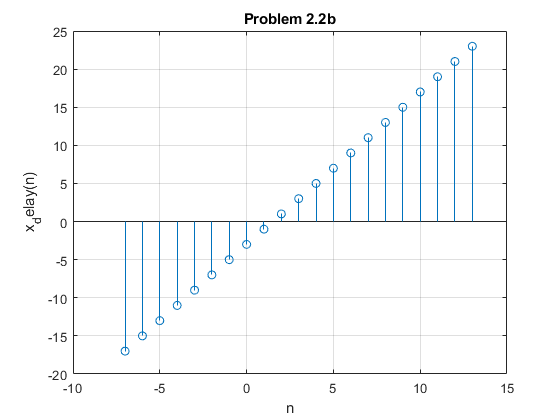

stem(n, x_delay)
grid on;
title('Problem 2.2b');
xlabel('n');
ylabel('x_delay(n)');


n = -10:10

n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


[x_reverse, n] = time_reversal(x, n)

x_reverse =     23    21    19    17    15    13    11     9     7     5     3     1    -1    -3    -5    -7    -9   -11   -13   -15   -17


n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


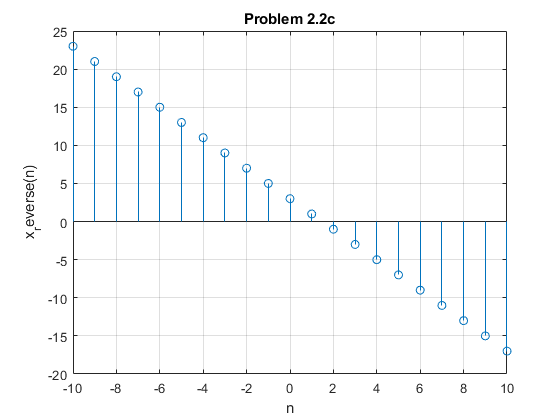

stem(n, x_reverse)
grid on;
title('Problem 2.2c');
xlabel('n');
ylabel('x_reverse(n)');

Problem 2.3

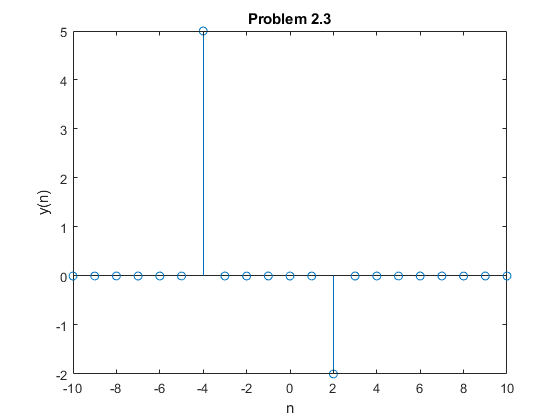

clear;
[y1, n] = unit_impulse(-4, -10, 10);
y1 = 5 .* y1;
[y2, n] = unit_impulse(2, -10, 10);
y2 = 2 .* y2;
y = y1 - y2;
stem(n, y)
title('Problem 2.3');
xlabel('n');
ylabel('y(n)');

Problem 2.4

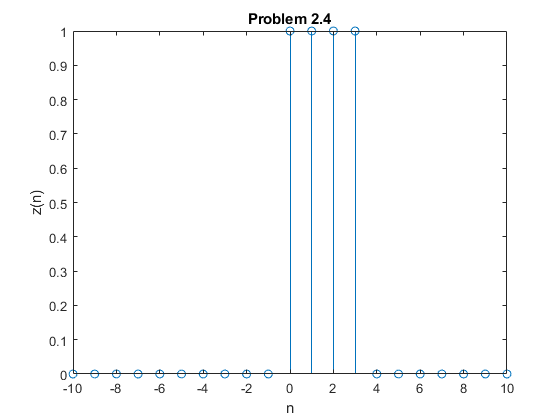

clear;
[y1, n] = unit_step(0, -10, 10);
[y2, n] = unit_step(4, -10, 10);
y = y1 - y2;
stem(n, y)
title('Problem 2.4');
xlabel('n');
ylabel('z(n)');

Problem 3

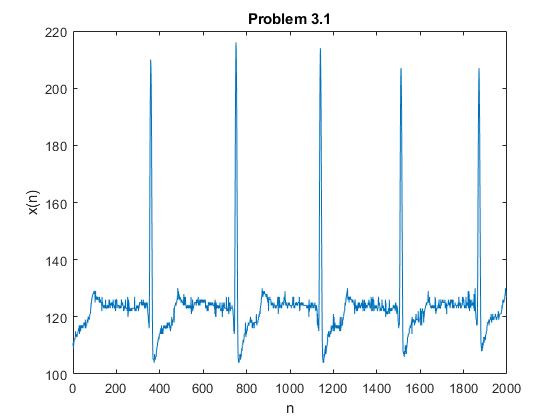

load('SAMPLE_ECG.mat')
x = ECG_Data;
n = 0:length(x)-1;

plot(n, x)
axis([0 2000 100 220]);
title('Problem 3.1');
xlabel('n');
ylabel('x(n)');

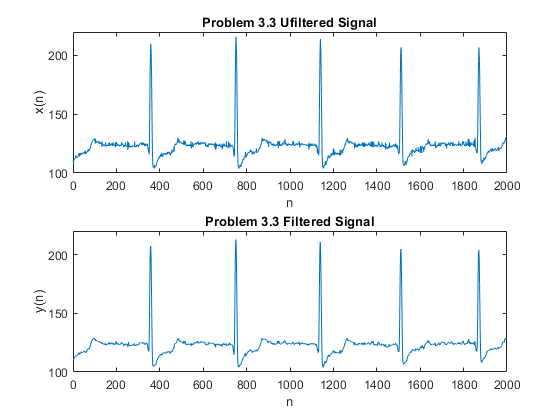


subplot(2, 1, 1)
plot(n, x)
axis([0 2000 100 220]);
title('Problem 3.3 Ufiltered Signal');
xlabel('n');
ylabel('x(n)');

for i = 1:length(x) - 2
   y(i) = (x(i) + x(i+1) + x(i+2)) / 3;
end

n = 0:length(x)-3;

subplot(2, 1, 2)
plot(n, y)
axis([0 2000 100 220]);
title('Problem 3.3 Filtered Signal');
xlabel('n');
ylabel('y(n)');

Problem 3.4

The signal y(n) is much smoother than x(n) and has much fewer visible noise and jumps. The filter effectively removed the high frequency noise.

Problem 1: Unit Impulse and Unit Step Functions

function [y,n] = unit_impulse(n_p, n1, n2)
   n = n1:n2;
   y = zeros(size(n));
   y(n == n_p) = 1;
end

function [y,n] = unit_step(n_p, n1, n2)
   n = n1:n2;
   y = zeros(size(n));
   y(n >= n_p) = 1;
end

function [y, n] = time_shift(x, n, n_d)
    n = n + n_d;
    y = x;
end

function [y, n] = time_reversal(x, n)
    y = fliplr(x);
    n = -fliplr(n);
end